# Flight Diagram of a Rocket

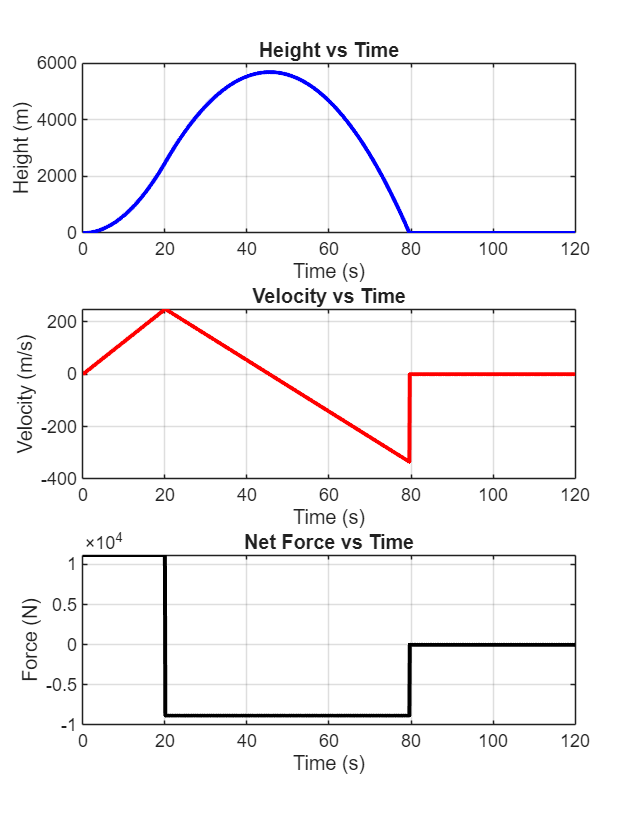

%{
ES115: Flight Diagram of a Rocket
Author: Jack O'charek
Date: 4-27-26
Purpose:
    Diagram the flight path of a rocket including all relevant metrics,
    namely height, velocity, net force, and time.
Input: N/A
Output:
    Three plots will be created, the first will show height versus time,
    the next will show velocity versus time, and the final will show net
    force versus time.
Engineering Algorithms
    Clear screen and delete all variables
    Define constants
    Initialize variables
    Create simulation loop and define relevant equations
    Define plot size
    Create plot for Height versus Time
    Create plot for Velocity versus Time
    Create plot for Net Force versus Time
%}
clc;
clear;
close all;

m = 900;             
g = 9.81;             

T_max = 20000;        
burn_time = 20;       

dt = 0.1;             
t = 0:dt:120;         

n = length(t);
h = zeros(1,n);      
v = zeros(1,n);       
a = zeros(1,n);     
F = zeros(1,n);       

for i = 1:n-1
    
    if t(i) <= burn_time
        T = T_max;
    else
        T = 0;
    end
    
    F(i) = T - (m * g);
    
    a(i) = F(i) / m;
    
    v(i+1) = v(i) + a(i)*dt;
    h(i+1) = h(i) + v(i)*dt;
    
    if h(i+1) < 0
        h(i+1) = 0;
        v(i+1) = 0;
        break;
    end
end
figure('Position', [100, 100, 700, 900]); 

subplot(3,1,1);
plot(t, h, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Height (m)');
title('Height vs Time');
grid on;

subplot(3,1,2);
plot(t, v, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs Time');
grid on;

subplot(3,1,3);
plot(t, F, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Force (N)');
title('Net Force vs Time');
grid on;